# Supervised Learning: Regression 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In this script, we use supervised learning to train a regression model that can predict the age of mollusks based on the number of rings on their shells.

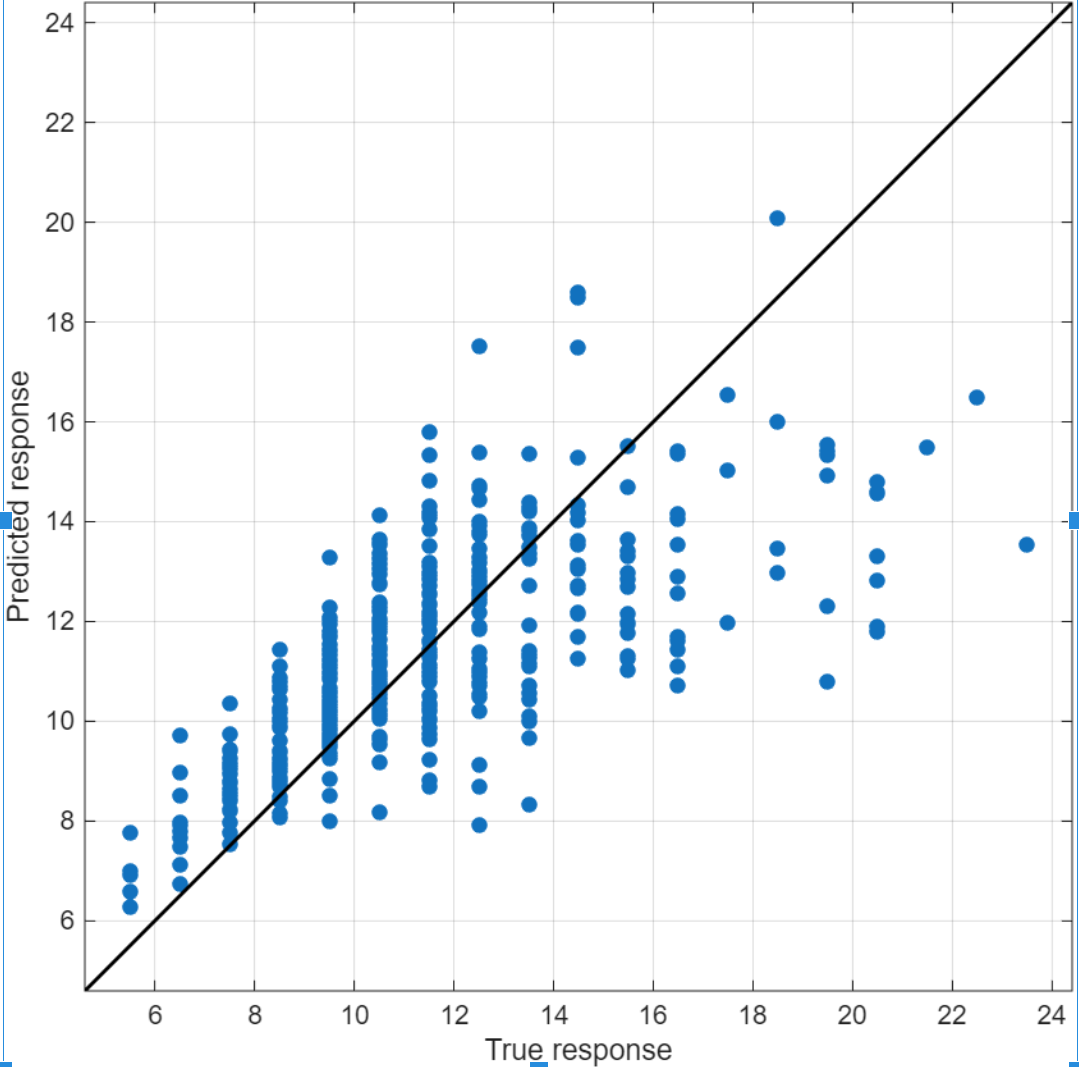

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Regression Learning

In **supervised learning**, tasks are typically categorized into classification and regression problems. While classification involves assigning inputs to discrete categories, **regression learning** focuses on predicting continuous numerical outcomes. Regression models are beneficial when the target variable represents a continuous measurable quantity such as blood pressure, cholesterol level, or the probability of a medical event that is based on a set of input features.

To illustrate a real-world application of regression, we will use a dataset from the UCI Machine Learning Repository about **abalone**, a genus of marine mollusks. A key biological characteristic of abalone is that their age can be estimated by counting the growth rings on their shells, much like with trees. Specifically, the number of rings plus a constant offset of ~1.5, provides a reasonable estimate of the abalone's age.

The objective in this regression task is to develop a predictive model that estimates the number of rings, or the age, of an abalone based on the dataset. This example uses the Abalone data [[3]](https://www.mathworks.com/help/releases/R2025a/stats/fsrftest.html#mw_ba5aa601-80b5-4cbf-9eda-fc91c3d2b0d7)[[4]](https://www.mathworks.com/help/releases/R2025a/stats/fsrftest.html#mw_b376f033-733f-4b72-993d-577e3a429dd8) from the UCI Machine Learning Repository [[5]](https://www.mathworks.com/help/releases/R2025a/stats/fsrftest.html#mw_f2b2f014-e160-44c9-9f8c-5f0de8c439bd).

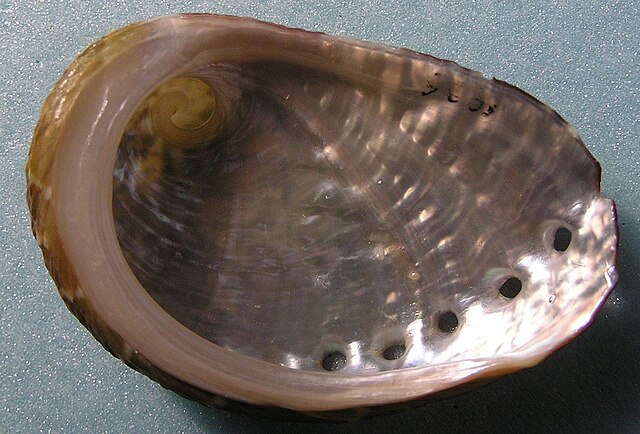

[Haliotis rugosa pustulata](https://commons.wikimedia.org/wiki/File:Haliotis_rugosa_pustulata_002.jpg), a sub-species of abalone typically found in Japanese coastal waters.

### Prepare Data for Machine Learning

To begin, we load and examine the dataset by reviewing its structure, contents, and dimensions. This step helps us understand what each patient sample represents and the amount of information contained within it. By familiarizing ourselves with the data early on, we set the stage for applying unsupervised learning techniques that can help us use regression learning to predict abalone age.

  **Try.** Load and format the data for machine learning. You can learn more about the `LoadAbalone` function [here](matlab: doc LoadAbalone).

 
Preview = true;
Help = true;
[AbaloneInputs, AbaloneTargets] = LoadAbalone(Preview,Help); % Live function to import data and format data into tables

 **Exercise 1. **How many shells are included in this dataset?

**Solution: **

CheckAnswer("Exercise1","4177"); % Non-default options include:1, 1.5, 8 and 4177

 **Exercise 2. **How many attributes are included in this dataset?

**Solution: **

CheckAnswer("Exercise2","8"); % Non-default options include:1, 1.5, 8 and 4177

#### Create a Data Table

We can calculate abalone age in years by adding 1.5 to the number of rings. So let's change our `abaloneTargets` array to contain age information instead: 

  **Try.** Calculate the age of the abalones and include it in the `abaloneTable`.

 
abaloneAge = AbaloneTargets + 1.5; % Calculate Abalone age from shells
abaloneTable = [AbaloneInputs, abaloneAge]; % Combine AbaloneInputs table with abaloneAge
disp("Displaying the first 10 rows of the Abalone Table.")
head(abaloneTable) % Display the first 10 rows of the abalone table

## Get Started with the Regression Learner App

We will use the [Regression Learner App](https://www.mathworks.com/help/stats/regression-learner-app.html) to do supervised learning on our data set. Before we open the app, let's look at the interface and get acquainted with it. After we load our data set, we will see a user interface with two distinct sections: Data set and Validation. 

**Data set section**

- In section A, **Data Set Variable**, the **Data Set Variable** section shows the data set you have loaded.

- In section B, the **Response** section, allows you to select a response variable from the data set variable or from the workspace.

- In section C, the **Predictors **section, your loaded data set is listed in a spreadsheet. You can scroll through the data set here. The Name, Type, and numeric Range are column headers. 

**Validation section**

- In section D, **Validation Scheme**, we can choose a validation method to examine the predictive accuracy of the fitted models. (We will stick with the default of Cross-Validation in this case). 

- In section E, the**Test** section, we can optionally choose to set aside a percentage of our test data set to use to validate our trained model. 

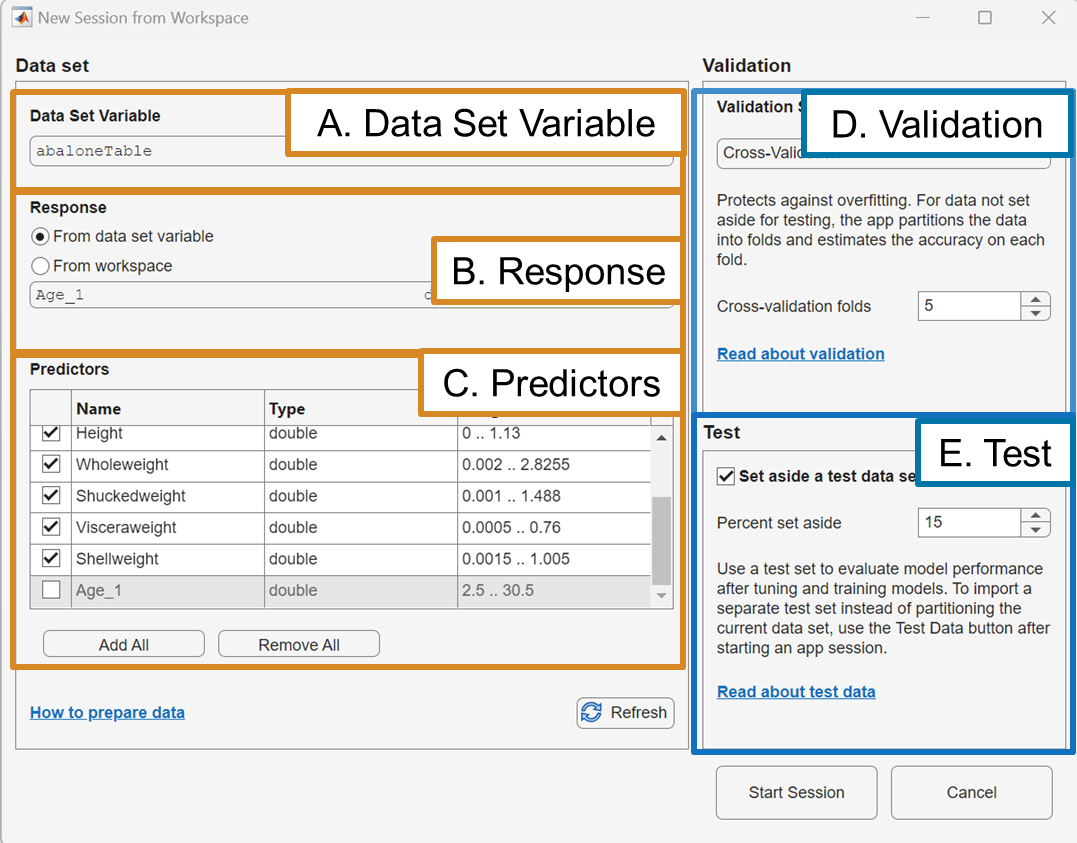

### Open Regression Learner App

Let's get started loading data into the [Regression Learner App](https://www.mathworks.com/help/stats/regression-learner-app.html).

  **Try.** Open the Regression Learner App.

 
regressionLearner

Once the **Regression Learner App** opens, follow the steps below.

- On the **Learn** tab, in the **File** section, click **New Session** and select data from the workspace. 

- In the New Session from Workspace dialog box, under **Data Set Variable**, select abaloneTable from the workspace variables.

- Check the **Set aside a test data set **box.

- Adjust the default value of 10 to 15 to set aside 15% of the data for testing under the Test section.

- Click **Start Session** to accept the default validation scheme and continue.

- A new window will open, and you will see a column titled Model, and a **response plot** similar to the one below. 

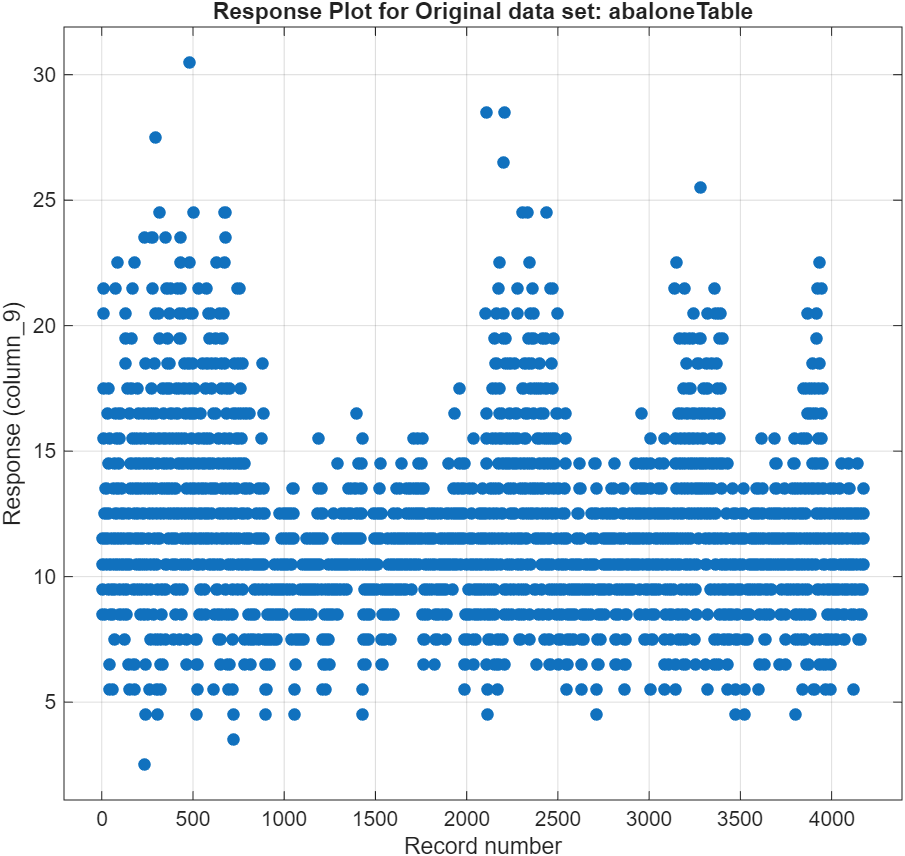

### Train the Model

After the **response plot** has appeared, you can begin to train your model. 

- In the **Models** section on the toolstrip, select **All Quick-To-Train **to train all the model presets that are fast to fit.

- In the **Train** section, click **Train All** and select **Train All**.

When using the Regression Learner App, you may notice that your results differ slightly from the sample outcomes. This variation is expected because the app uses random sampling to hold back part of the data for validation or testing, which helps prevent overfitting. Additionally, some regression algorithms include random elements, such as how data is split or how model parameters are initialized, which can lead to slightly different results each time you train. The sample outcomes are intended to provide a general idea of expected performance rather than an exact match.

The training can take up to 5 minutes because the all quick to train option trains the data on six different training models. You will see results similar to those below. If you set aside a different percentage different than the 15% suggested in the directions. You will see two outcomes: a list of the **Models** trained along with their accuracy on the left, and a **Response Plot **for Predictions on the right. For each model trained, the App will generate the Name of the model, the **Accuracy (validation)** percentage, and an accounting of the number of features tested. 

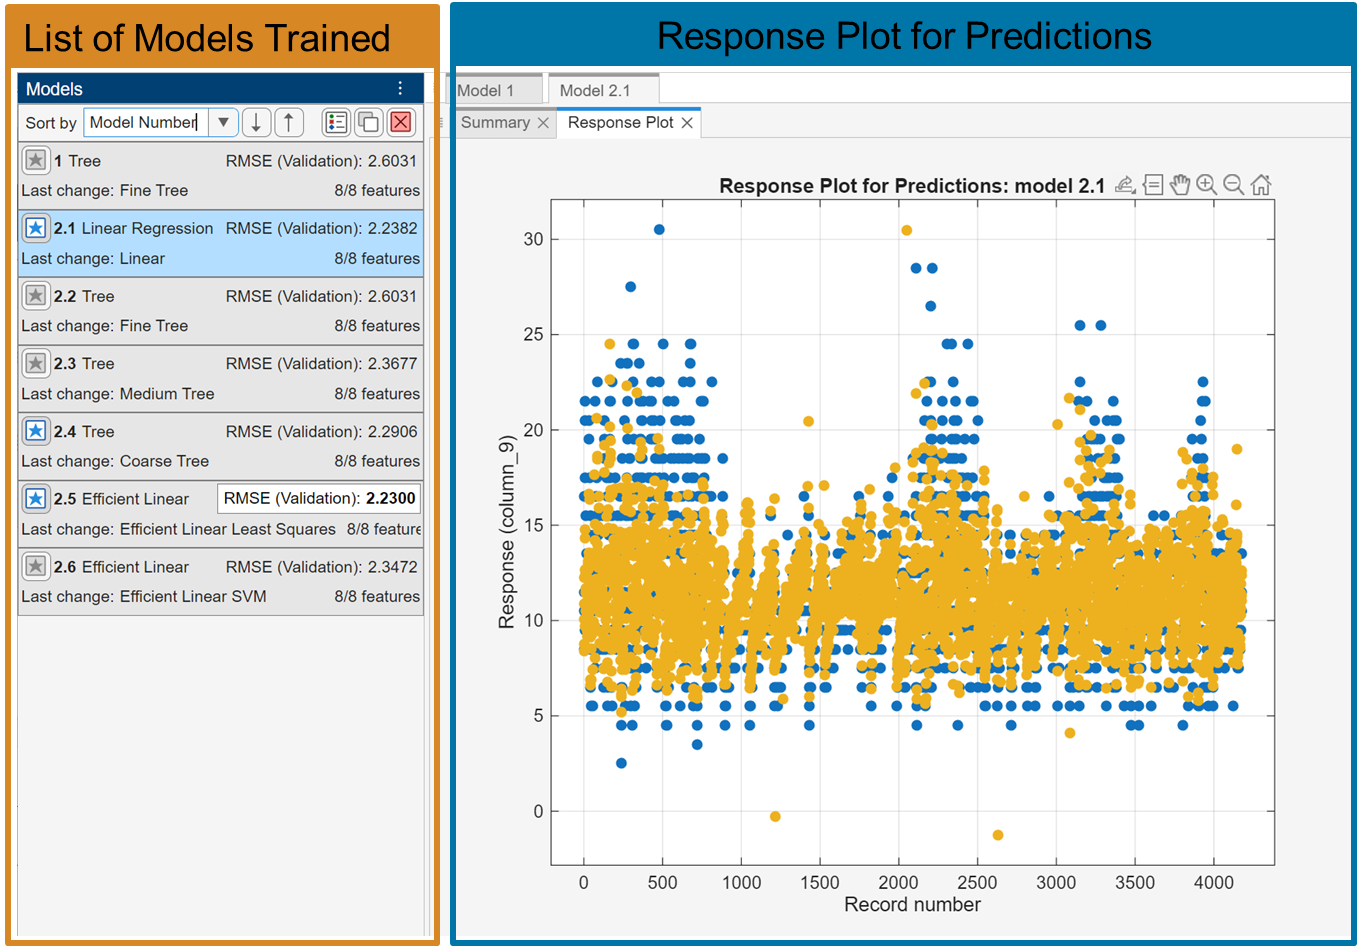

### Use Feature Selection to Improve your Model

A lower RMSE value means that your model's predictions are closer to the actual values, indicating better accuracy. Therefore, we will choose our best model based on the lowest RMSE Validation value. Feature selection identifies the most relevant input predictor variables or features to improve model accuracy and interpretability while also reducing overfitting and enhancing performance in resource-limited environments. It is possible that some of the features do not contribute equally to the prediction of the abalone age and that some of these predictors do not contribute significantly to the predictive power of our algorithm. Therefore, we can identify the features critical for the accurate prediction of the abalone age with feature selection. You can learn more about feature selection in [What is Feature Selection](https://www.mathworks.com/discovery/feature-selection.html?s_tid=srchtitle_site_search_1_feature+selection+regression).

We will select the MRMR feature ranking algorithm, which selects features that are highly correlated with the target variable while minimizing redundancy among them, ensuring each chosen feature contributes unique and meaningful information to the model. By minimizing redundancy and focusing on relevance, MRMR improves a model’s ability to generalize to unseen data, which is especially important in biological datasets like abalone shells, where subtle patterns can influence predictions.

- Use the **Sort by** list at the top of the **Models** pane to rank models by **RMSE Validation. **

- You can then use the up arrow  to sort this list in ascending order. To select a metric for model sorting, 

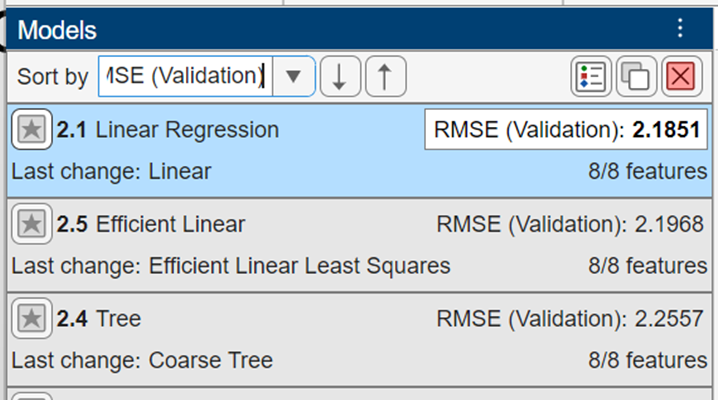

3. Right-click on the top-performing test, the one with the lowest **RMSE (Validation)** and select **Duplicate** from the dropdown menu.

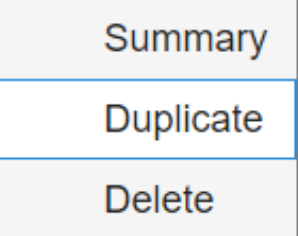

4. A new model will open, and then you can do Feature Selection for the models by identifying the predictors that contribute most to the prediction of abalone age.  

   

5. Select MRMR from the available feature ranking algorithms to select features. You will see a graph of Feature importance scores paired with a Feature Selection table.

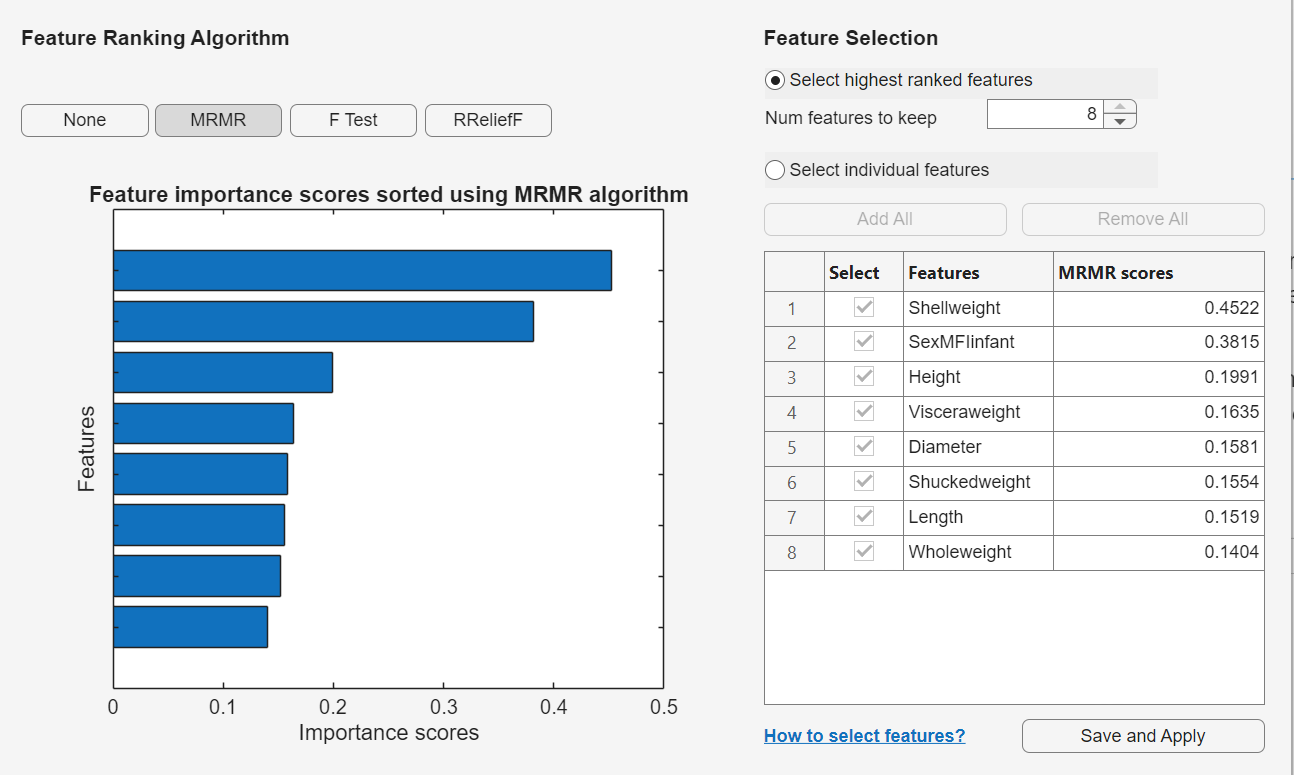

6. Choose Select individual features and then select the highest-ranked individual features. In the table below, there are three individual features chosen.

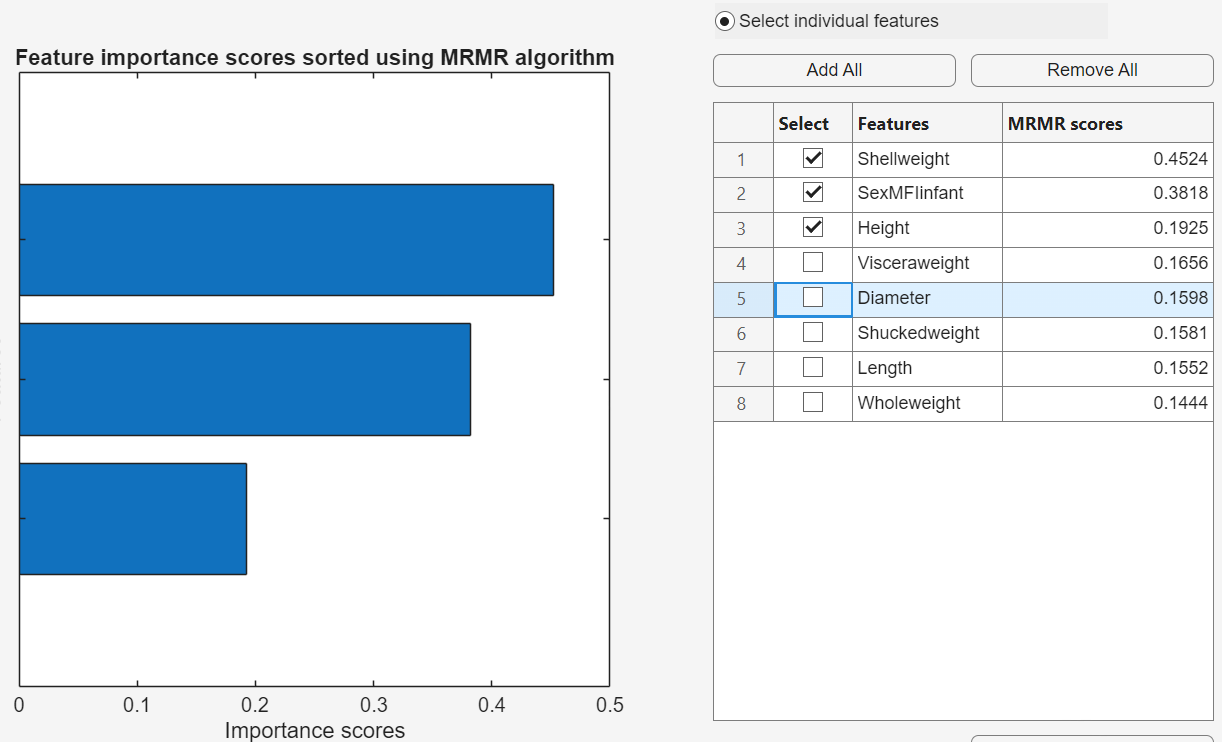

7. Press the **Save and Apply** button.

#### Reduce Dimensionality with PCA 

- With your selected model draft highlighted, in this case, the Linear Regression model, on the **Learn** tab, in the **Options** section, select **PCA**.

- In the Default PCA Options dialog box, select the **Enable PCA** check box, and then click **Save and Apply**.

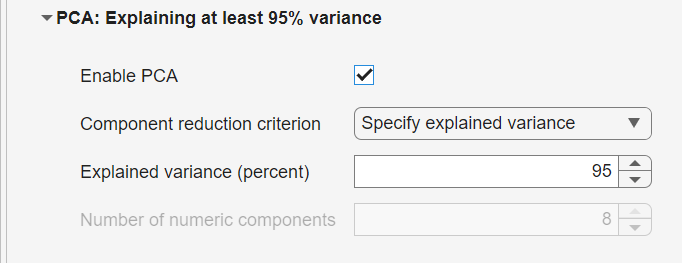

3. In the **Train** section, select the **Train Selected **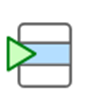button to retrain the model on only the PCA options that explain 95% of the model variance.

4. Under the **Response** **Plot** tab, you will see a scatter plot displaying the True and predicted values like the one below.

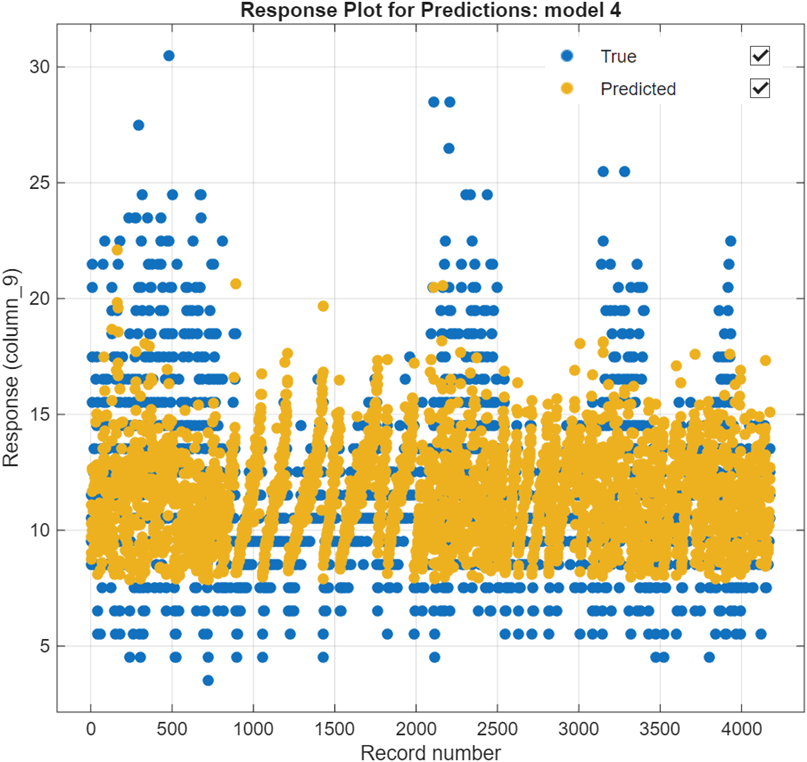

5. To the left of the Response Tab, you can find the Summary tab. 

5. Scroll to the PCA section on the Summary tab and expand the PCA menu by pressing the down button. You will see a result similar to the one below.

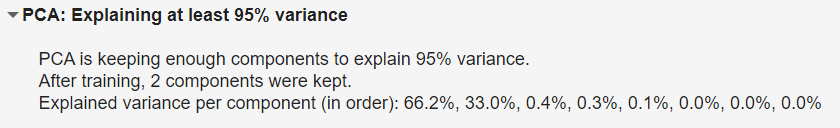

#### Retrain the models on selected features

- On the **Learn** tab, in the **Train** section, click **Train All** and select **Train All** or **Train Selected**.

- Select the model trained with the feature selection in the **Models** pane.

- On the **Learn** tab, in the **Plots and Results** section, and then click **Residuals (Validation)** in the **Validation Results** group.

- The residuals plot displays the difference between the predicted and true responses. To display the residuals as a line graph, in the **Style** section, choose **Lines**.

For the model trained with feature selection, you may get a residual plot like the one below:

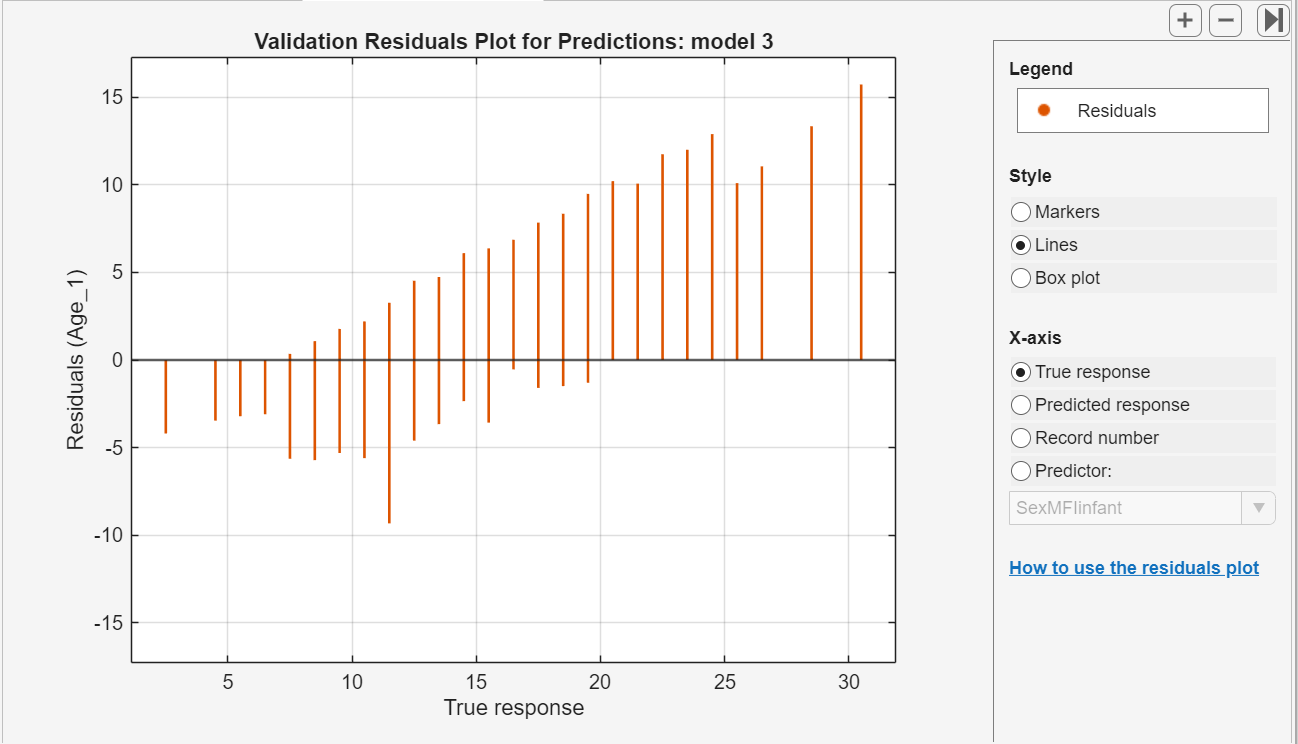

 **Reflect**. Based on the characteristics of a good model, in which the residuals are relatively symmetric around 0. Clear patterns tell us that we can likely improve our models; however, if we see residuals not symmetrically distributed around 0 or residuals changing significantly from left to right, we may have a misspecified model, meaning we may be missing important variables, or our model is non-linear. 

### Test the Model

At the start of our process, we set aside 15% of the dataset, which has not been used in any training or validation steps, thereby leaving this data completely unseen by the model.

We are now ready to evaluate the models on this untouched data. The key question is:** How well do the models perform on data it has never encountered before?** When we relate this question to our initial problem statement, how well will these models be able to predict abalone age from the number of shells?

Let's test the models, specifically looking at the two Linear Regression models: one with all features included, and the other with only a couple of features included. 

- In the **Test** tab, we will select **Test All** and train our two models. 

- On the **Learn** or **Test** tab, in the **Plots and Results** section, click **Compare Results **to see a plot showing a bar chart of validation RMSE for the models, ordered from lowest to highest RMSE value. 

- You can sort the models by other training and test results using the **Sort by** list under **Sort Data**. 

- You can also group models of the same type, select **Group by model type** to see if a particular model type performs better than another model type. 

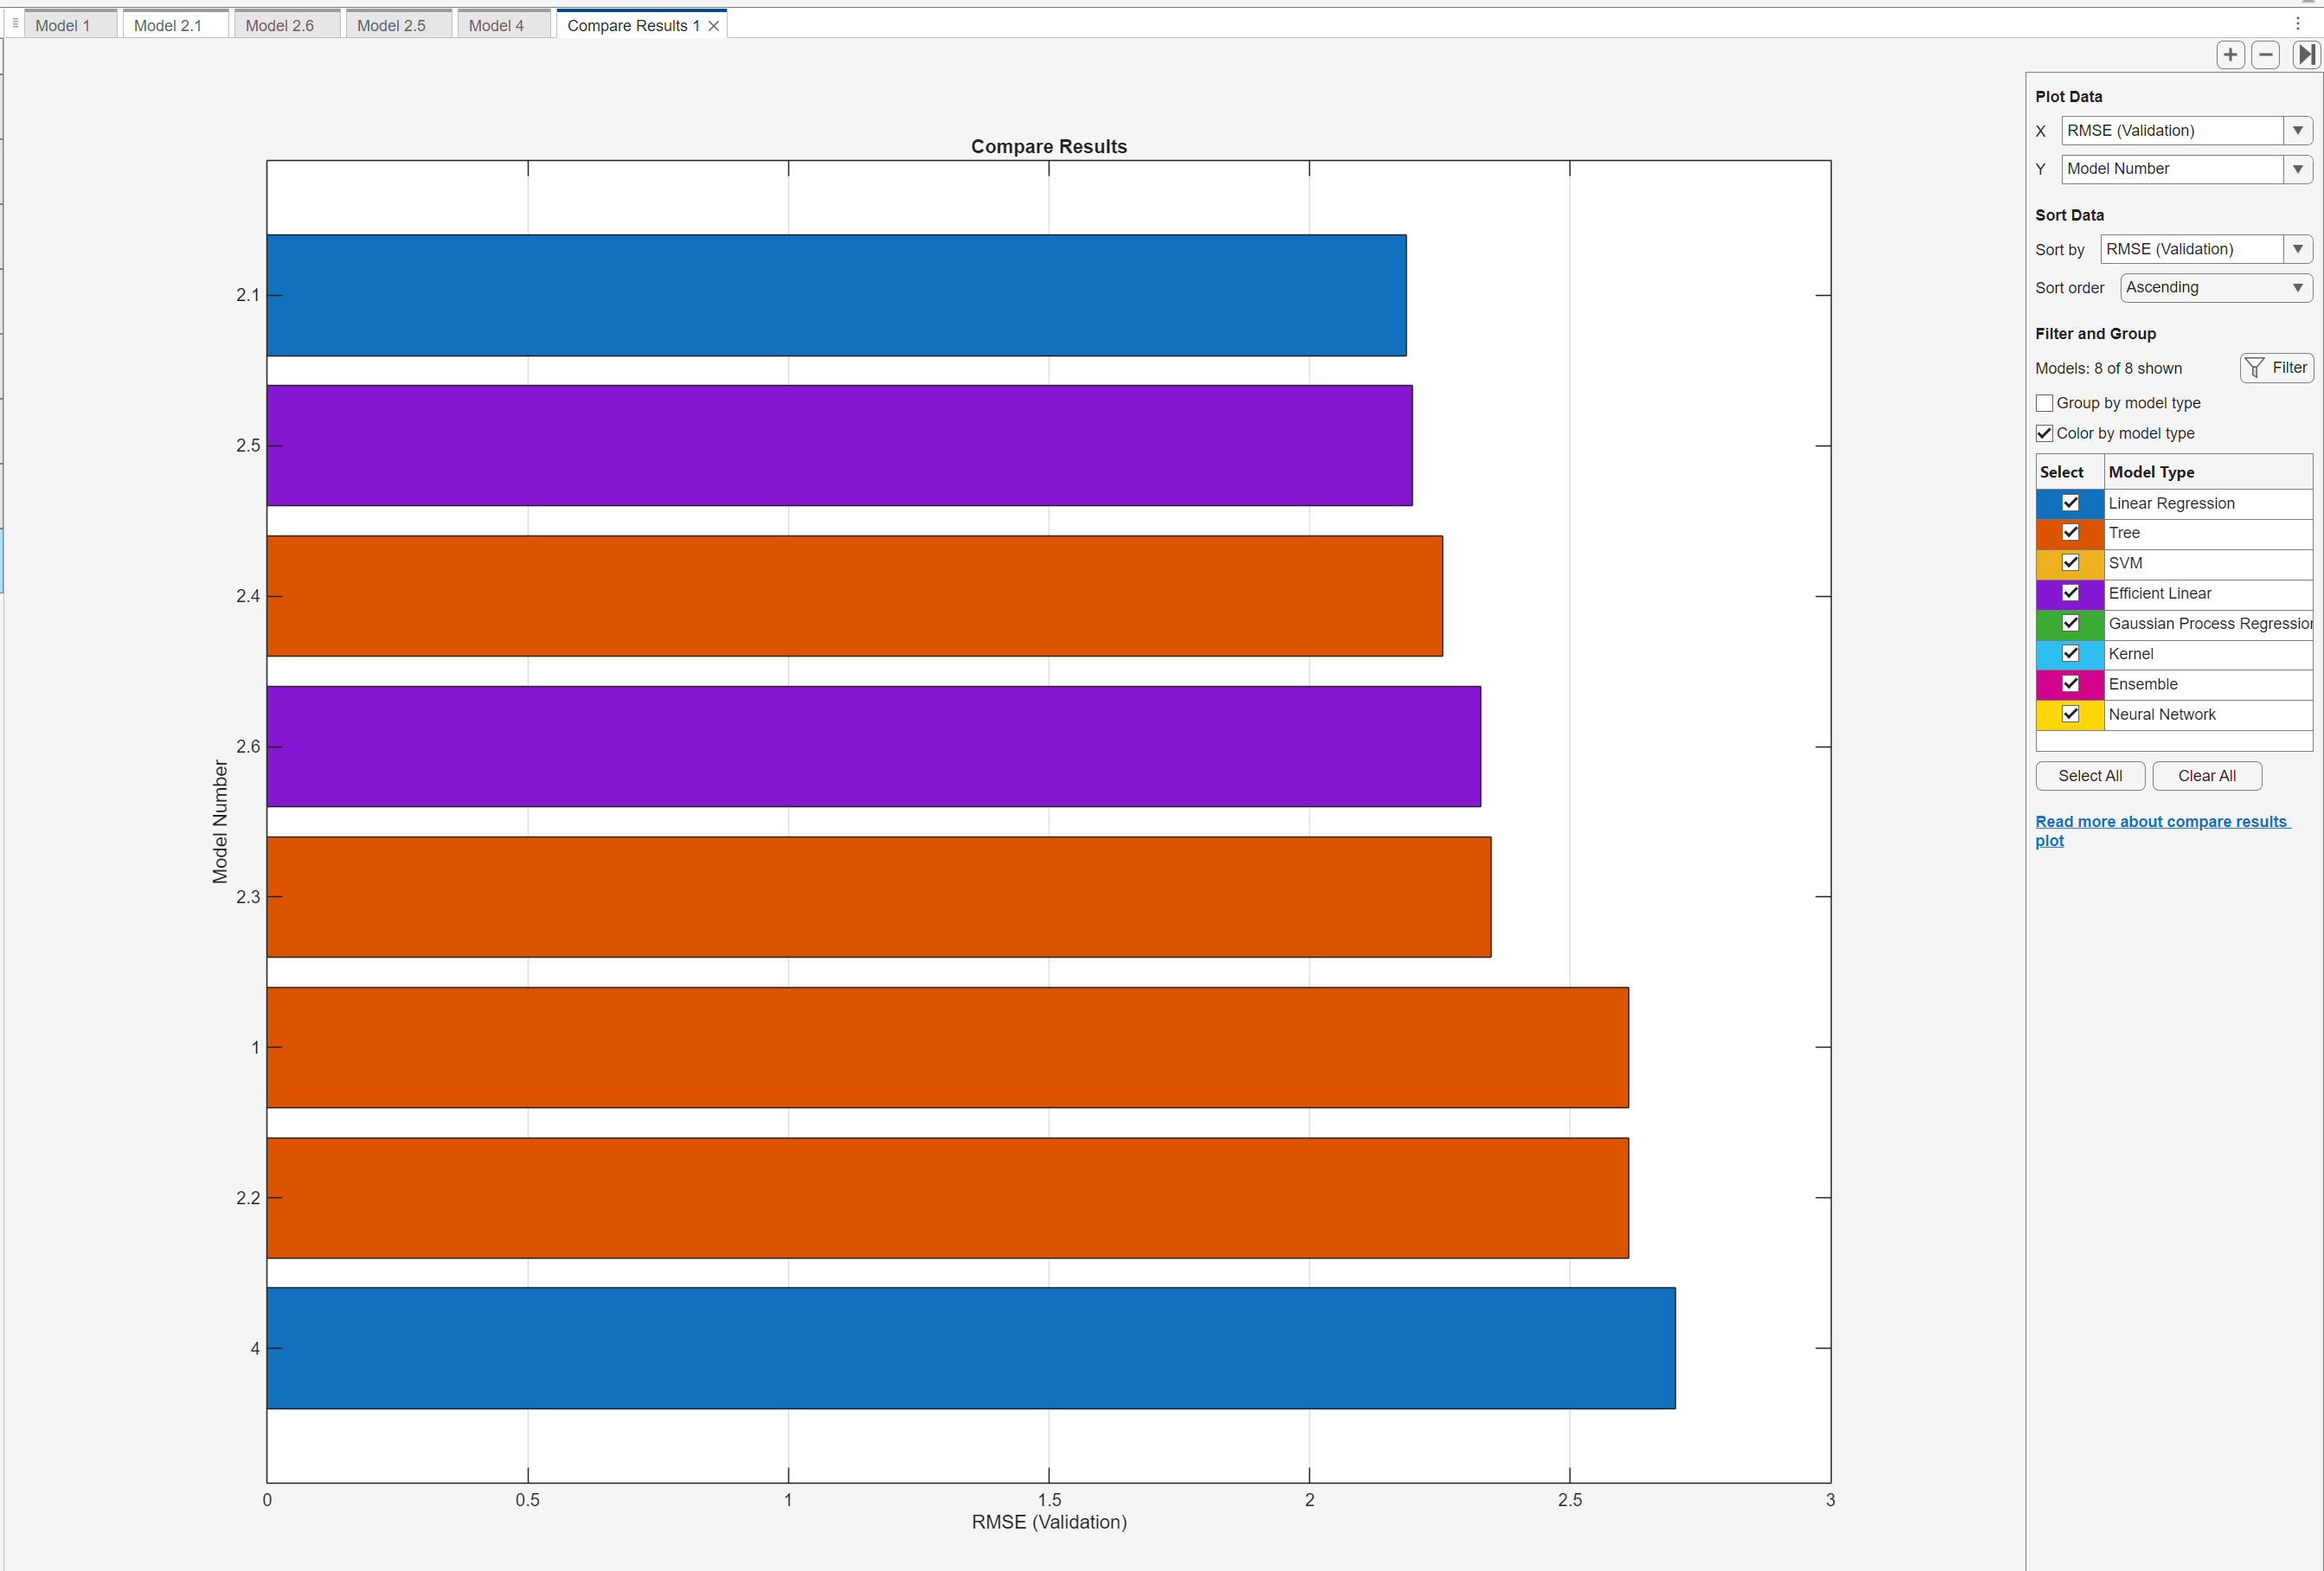

### **Plot Predicted vs. Actual Response**

Use the Predicted vs. Actual plot to check model performance to help you understand how well the regression model makes predictions for different response values. You can view the Predicted vs. Actual plot after testing a model.

- In the **Test** table, select the Predicted vs. Actual (Test) icon 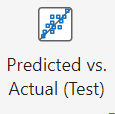, 

- A plot of the predicted response of your model is plotted against the actual, true response, where the observations are the points, and the perfect prediction which is a line.

A perfect regression model has a predicted response equal to the true response, so all the observation points lie on a diagonal line. The vertical distance from the line to any point is the error of the prediction for that point. A good model has small errors, which means the predictions are scattered near the line.

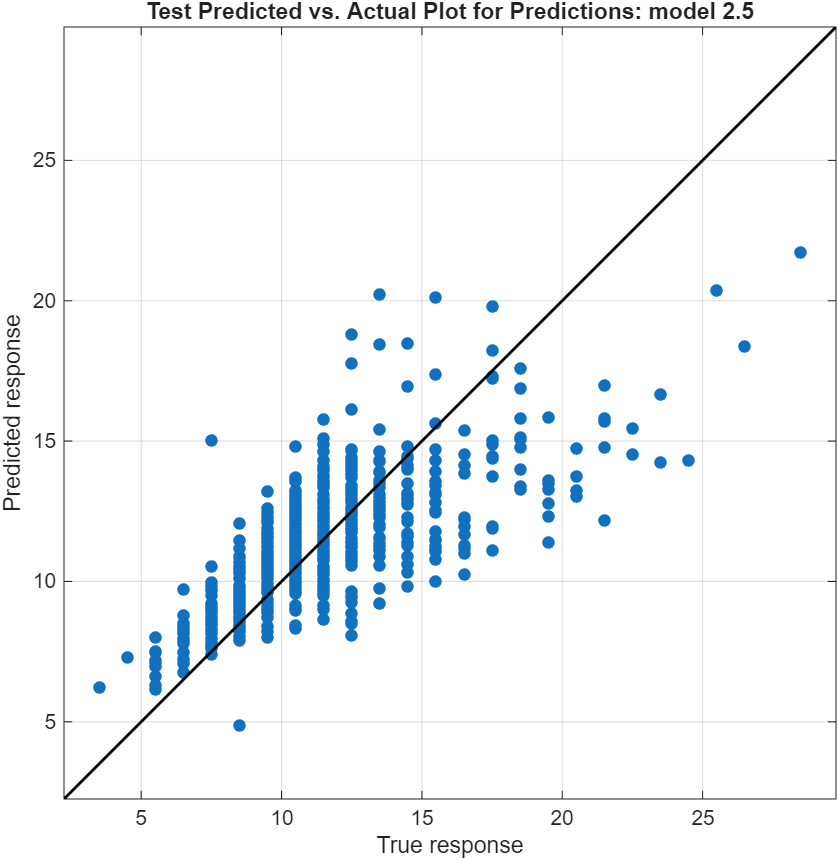

### **Compare Model Information and Results in Table View**

Rather than using the **Summary** tab or the **Models** pane to compare model metrics, you can use a table of results. On the **Learn** tab, in the **Plots and Results** section, click **Results Table**. In the **Results Table** tab, you can sort models by their training and test results, as well as by their options (such as model type, selected features, PCA, and so on). For example, to sort models by root mean squared error, click the sorting arrows in the **RMSE (Validation)** column header. An up arrow indicates that models are sorted from lowest RMSE to highest RMSE.

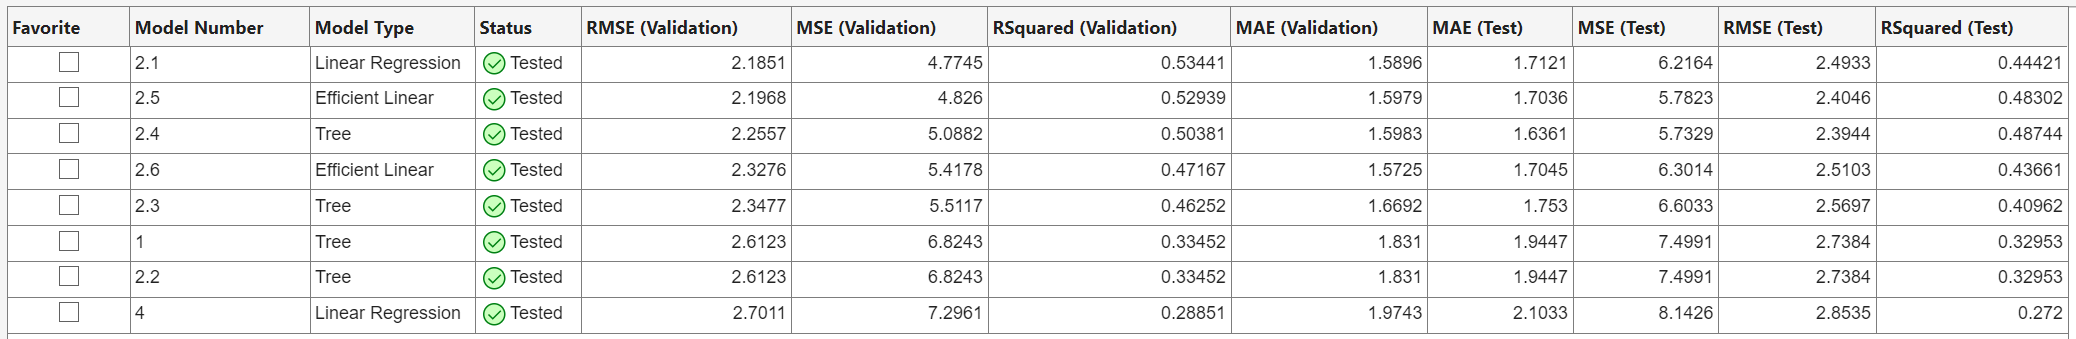

As we evaluate these results, we can compare our statistical metrics. 

- **RMSE (Root Mean Square Error)**: Lower is better. Measures average prediction error magnitude.

- **MSE (Mean Squared Error)**: Like RMSE but not square-rooted. Also, lower is better.

- **R² (R-Squared)**: Higher is better. Indicates how well the model explains the variance in the data (1 = perfect fit, 0 = no fit).

- **MAE (Mean Absolute Error)**: Lower is better. Measures the average absolute difference between predicted and actual values.

 **Reflect**. Based on the statistical metrics above, which models are performing the best? Try experimenting with the Regression Learner by increasing the number of cross-validation folds to enhance training accuracy. You can also reserve up to 20% of your data for testing to better evaluate how your model performs on unseen data. This is a great way to refine your model and gain deeper insights! You can begin a new session by going to the **Learn** tab, in the **File** section, click **New Session** and selecting the data from the workspace. 

## Glossary

**Regression learning: **A supervised learning task focused on predicting continuous numerical values, such as temperature, price, or age. (↑ Return to Text)

**Supervised** **learning: **A type of machine learning where the model is trained on labeled data to learn the relationship between inputs and known outputs. (↑ Return to Text)

## Further Exploration

You can explore further into regression algorithms in [**Regression Basics**](https://www.mathworks.com/matlabcentral/fileexchange/93435-regression-basics)**.**

You can explore further into [**Machine Learning for Regression**](https://www.mathworks.com/matlabcentral/fileexchange/95903-machine-learning-for-regression)**.**

Try these examples from the documentation to learn more about using the [Regression Learner App](https://www.mathworks.com/help/stats/regression-learner-app.html).

- [**Train Regression Models in Regression Learner App**](https://www.mathworks.com/help/stats/train-regression-models-in-regression-learner-app.html)

- [**Select Data and Validation for Regression Problem**](https://www.mathworks.com/help/stats/select-data-and-validation-for-regression-problem.html)

- [**Automated Regression Model Training**](https://www.mathworks.com/help/stats/train-regression-models-in-regression-learner-app.html#bvi2d7_-4)

- [**Train Regression Trees Using Regression Learner App**](https://www.mathworks.com/help/stats/train-regression-trees-using-regression-learner-app.html)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option) % Function to check answers for exercises
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1",struct("answer","4177","hint","Based on the dimensions of the abaloneInputs matrix, how many individual abalone shells are included in the dataset?"),...
    "Exercise2",struct("answer","8","hint","How many rows are in the abaloneInputs matrix, and what does each row represent?")...
    );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.")
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        warning("%s",hint)
    end
else
    warning("Exercise not found.")
end
end